r=0.56 

r = 0.5600

k=5E8

k = 500000000

P0=3000*120

P0 = 360000

total_days=25

total_days = 25


dt_values=[1/24,1/440,1/86400]

dt_values =     0.0417    0.0023    0.0000


colors=['r','g','b']

colors = 'rgb'

pop_at_3_days=zeros(length(dt_values),1);
figure;
for i=1:length(dt_values)
    dt=dt_values(i)
    num_steps=ceil(total_days/dt)
    t=(0:num_steps)*dt
    P=zeros(size(t))
    P(1)=P0

    for n=1:num_steps
        dPdt=r*P(n)*(1-P(n)/k);
        P(n+1)=P(n)+dPdt*dt;
    end
    
    idx_3_days=find(t>=3,1);
    pop_at_3_days(i)=P(idx_3_days);

    subplot(3,1,1);
    plot(t,P,colors(i));hold on;
    title('Population Growth P(t)');
    xlabel('Time(days)'); ylabel('Population');

    subplot(3,1,2);
    dPdt=r*P.*(1-P/k);
    plot(t,dPdt,colors(i));hold on;
    title('Growth Rate dP(t)/dt');
    xlabel('Time(days)'); ylabel('Growth Rate');
end

dt = 0.0417

num_steps = 600

t =          0    0.0417    0.0833    0.1250    0.1667    0.2083    0.2500    0.2917    0.3333    0.3750    0.4167    0.4583    0.5000    0.5417    0.5833    0.6250    0.6667    0.7083    0.7500    0.7917    0.8333    0.8750    0.9167    0.9583    1.0000    1.0417    1.0833    1.1250    1.1667    1.2083    1.2500    1.2917    1.3333    1.3750    1.4167    1.4583    1.5000    1.5417    1.5833    1.6250    1.6667    1.7083    1.7500    1.7917    1.8333    1.8750    1.9167    1.9583    2.0000    2.0417


P =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P =       360000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


dt = 0.0023

num_steps = 11000

t =          0    0.0023    0.0045    0.0068    0.0091    0.0114    0.0136    0.0159    0.0182    0.0205    0.0227    0.0250    0.0273    0.0295    0.0318    0.0341    0.0364    0.0386    0.0409    0.0432    0.0455    0.0477    0.0500    0.0523    0.0545    0.0568    0.0591    0.0614    0.0636    0.0659    0.0682    0.0705    0.0727    0.0750    0.0773    0.0795    0.0818    0.0841    0.0864    0.0886    0.0909    0.0932    0.0955    0.0977    0.1000    0.1023    0.1045    0.1068    0.1091    0.1114


P =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P =       360000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


dt = 1.1574e-05

num_steps = 2160000

t =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006


P =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P =       360000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0



legend(cellstr(num2str(dt_values','\change t=%.0e')));

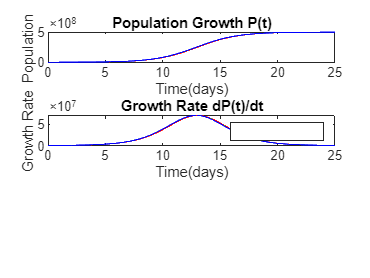

hold off;

smallest_dt_pop=pop_at_3_days(end)

smallest_dt_pop = 1.9255e+06

errors=abs((pop_at_3_days(1:end-1)-smallest_dt_pop)/smallest_dt_pop)*100

errors =     1.8969
    0.1054


disp('Population at 3 days for each\change t:')

Population at 3 days for each\change t:


for i=1:length(dt_values)
    fprintf('dt=%.0e: P(3)=%.2f cells\n',dt_values(i), pop_at_3_days);
end

dt=4e-02: P(3)=1889010.93 cells
dt=2e+06: P(3)=1925537.36 cells
dt=2e-03: P(3)=1889010.93 cells
dt=2e+06: P(3)=1925537.36 cells
dt=1e-05: P(3)=1889010.93 cells
dt=2e+06: P(3)=1925537.36 cells



fprintf('\nPercentage errors compared to smalles\change t:\n');


Percentage errors compared to smalles

for i=1:length(errors)
    fprintf('dt=%.0e: Error=%.2f%%\n',dt_values(i), errors(i));
end

dt=4e-02: Error=1.90%
dt=2e-03: Error=0.11%
